# Part 3: Shock vs. Reward

Analyses for Experiment 3

## A: Set up variables

xticklabels = {'SHK' 'CTL' 'RWD'};
exp_ind = find(strcmp(rdb.experiment, 'org'));
 
[u_paircodes, ia_pairs, ic_pairs] = unique(rdb.paircode(exp_ind));
 condvec = [5 2 4]; % 1 min 45 min 1 day
 phystypes = [-1 1 2 3];
 betypes = phystypes;%oops. Used phystypes a few places. But I meant betypes. Now they'll be the same. ]]></w:t></w:r></w:p><w:p><w:pPr><w:sectPr/></w:pPr></w:p><w:p><mc:AlternateContent xmlns:mc="http://schemas.openxmlformats.org/markup-compatibility/2006"><mc:Choice Requires="R2018b"><w:pPr><w:pStyle w:val="heading2"/><w:jc w:val="left"/></w:pPr></mc:Choice><mc:Fallback><w:pPr><w:pStyle w:val="heading"/><w:jc w:val="left"/></w:pPr></mc:Fallback></mc:AlternateContent><w:bookmarkStart w:name="MW_H_3B86E0E3" w:id="H_3B86E0E3"/><w:r><w:t>1.1 Physical interactions protocol</w:t></w:r><w:bookmarkEnd w:id="H_3B86E0E3"/></w:p><w:p><w:pPr><w:pStyle w:val="text"/><w:jc w:val="left"/></w:pPr><w:r><w:t></w:t></w:r></w:p><w:p><w:pPr><w:pStyle w:val="code"/></w:pPr><w:r><w:t><![CDATA[%open Desktop\Degu\reunion\Lidhar_ReunionMotivation_Figure1.pptx]]></w:t></w:r></w:p><w:p><w:pPr><w:sectPr/></w:pPr></w:p><w:p><mc:AlternateContent xmlns:mc="http://schemas.openxmlformats.org/markup-compatibility/2006"><mc:Choice Requires="R2018b"><w:pPr><w:pStyle w:val="heading2"/><w:jc w:val="left"/></w:pPr></mc:Choice><mc:Fallback><w:pPr><w:pStyle w:val="heading"/><w:jc w:val="left"/></w:pPr></mc:Fallback></mc:AlternateContent><w:bookmarkStart w:name="MW_H_F38EEFDC" w:id="H_F38EEFDC"/><w:r><w:t>1.2 Physical interactions: combined</w:t></w:r><w:bookmarkEnd w:id="H_F38EEFDC"/></w:p><w:p><w:pPr><w:pStyle w:val="code"/></w:pPr><w:r><w:t><![CDATA[% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1.1 Total physical interaction data
behaviortypes = {'Agonistic' 'Grooming' 'Rear-sniffing' 'Face-to-face'};

## B: Physical interaction

### B.1 Physical interactions, combined

septime_mat = nan(length(u_paircodes),length(condvec),length(phystypes));
 for i = 1:length(u_paircodes)
    for j = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(j)), exp_ind);
         septime_mat(i,j,1:length(phystypes)) = sum(rdb.sumbehav(curind,:),1);
    end
 end
 
 %something is wrong with one of the sessions (probably the recorded session start/end times)
 % for now we will remove
% septime_mat(end, end, :) = nan;
 

#### Figure of total physical interaction data

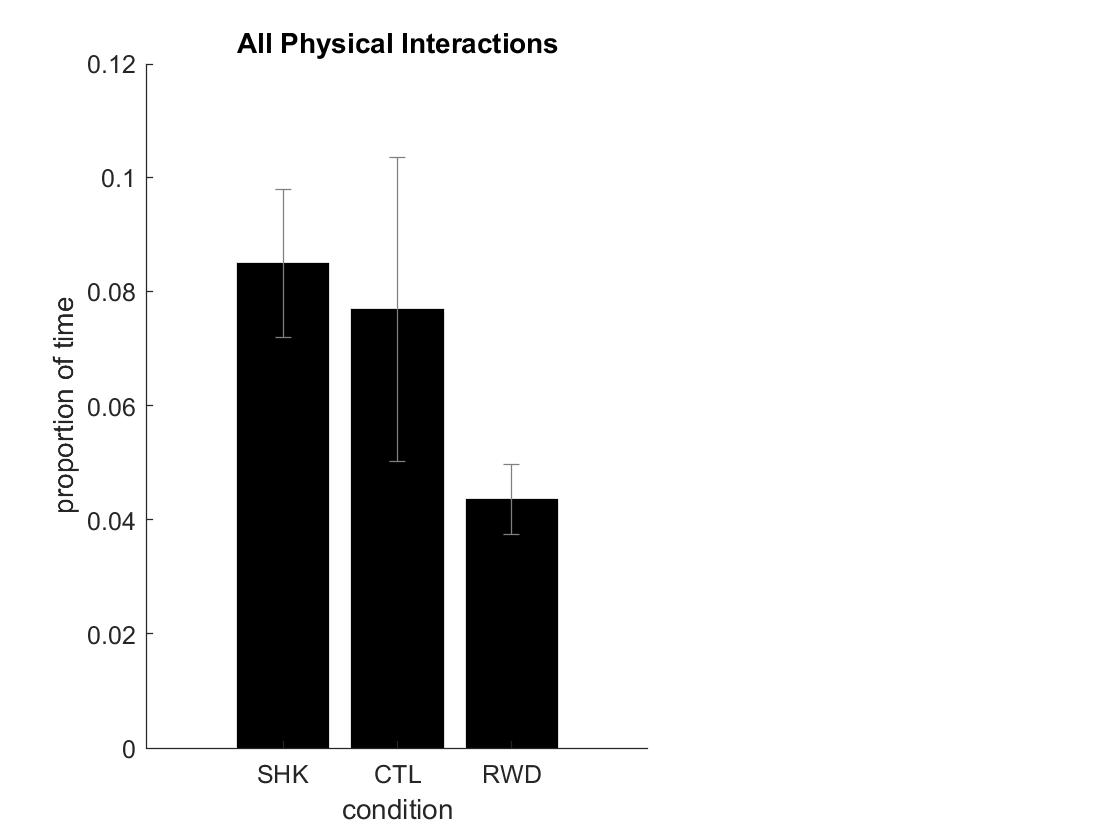

 stm_all = nansum(septime_mat,3);
 
% not normalized:
 figure
 f2A = subplot(1,5,1:3);
 bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
 hold on;
 eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
 set(f2A, 'XTickLabel', xticklabels);
 set(get(f2A, 'XLabel'), 'String', 'condition');
 set(get(f2A, 'YLabel'), 'String', 'proportion of time');
 set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
 box off

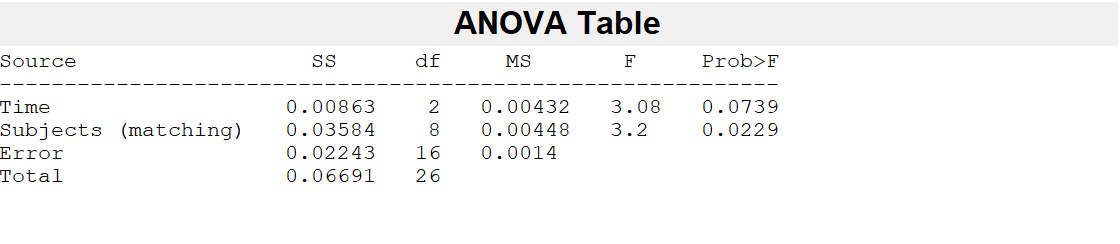

 [p, table] = anova_rm(stm_all);

 
 [a b] = ttest(stm_all(:,2)-stm_all(:,3))

a = 0

b = 0.1417

[a b] = ttest(stm_all(:,1)-stm_all(:,3))

a = 1

b = 0.0058

 [a b] = ttest(stm_all(:,1)-stm_all(:,2))

a = 0

b = 0.6985

### B.2 Physical interaction types

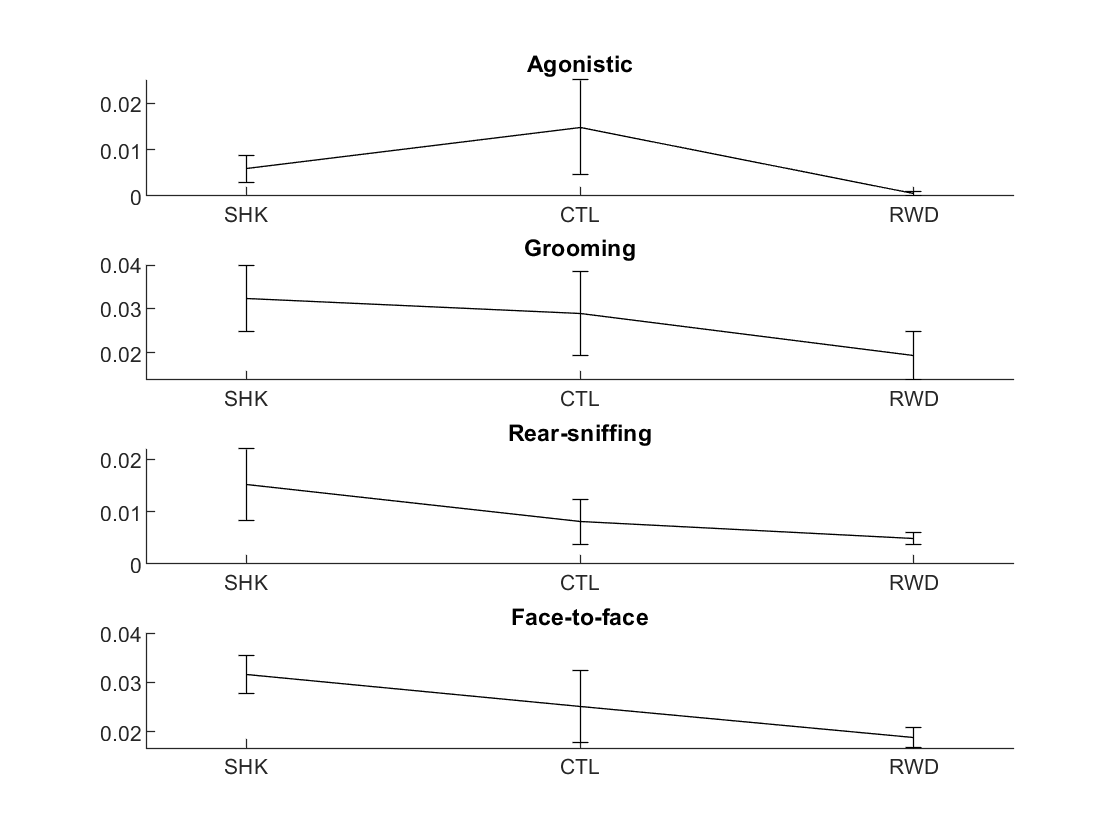



figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_mat(:,:,i)), nanstd(septime_mat(:,:,i))/sqrt(size(septime_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

 for i = 1:4
     [a(i) b(i)] = ttest(septime_mat(:,1,i)-septime_mat(:,2,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end
 
 b

b =     0.4146    0.4287    0.0757    0.3884


  for i = 1:4
     [a(i) b(i)] = ttest(septime_mat(:,1,i)-septime_mat(:,3,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
  end
  b

b =     0.0811    0.0370    0.1558    0.0298


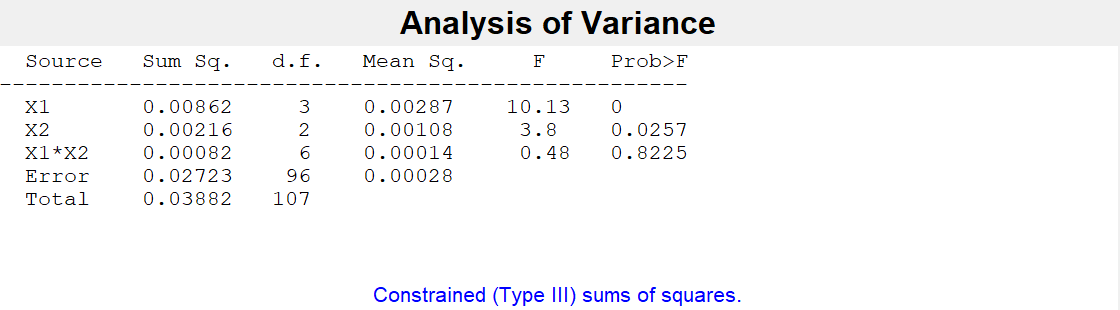

 
 s = septime_mat(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

2-way repeated measures ANOVA in R

 Create_2way_R_table(septime_mat(:,1:2,:));
 
 % Have to use R script for stats (e.g., repeatedmeasures_NIscript.R)
 
 


####  B.2.b Re-examine with only the first 10 min

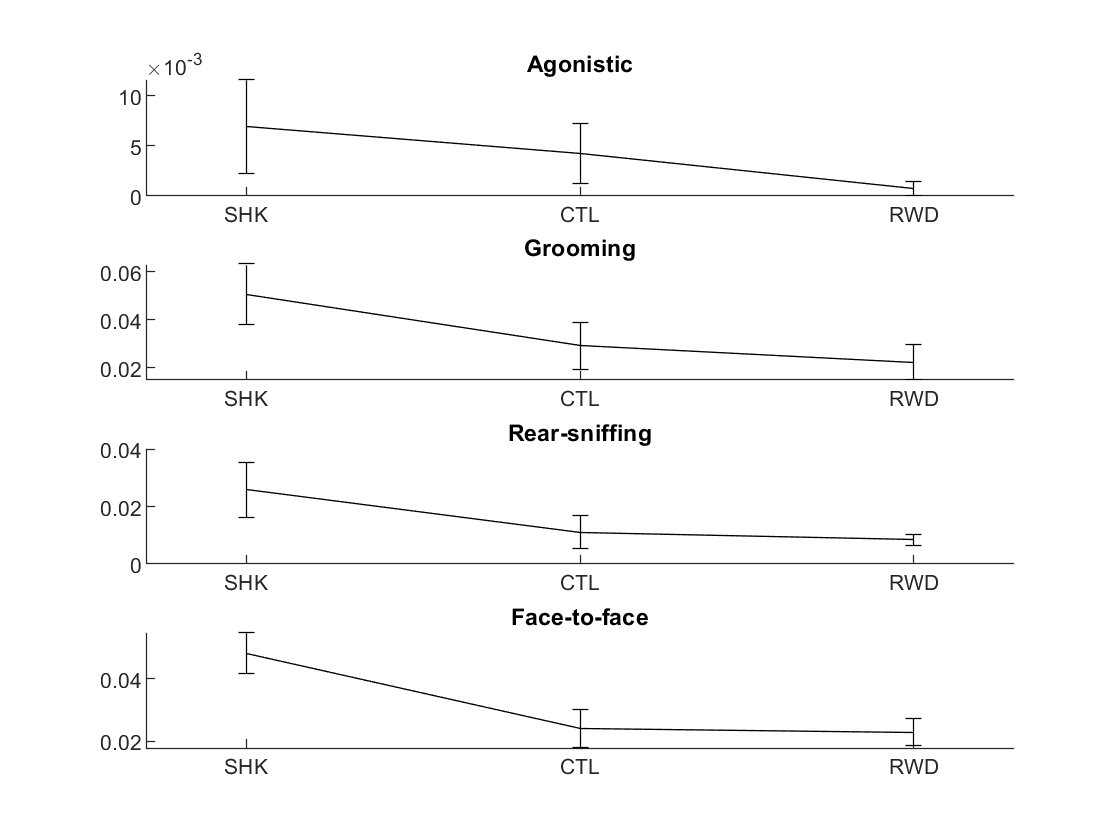

sumbehav_half =  reun_mksumbehav(rdb, betypes, 1, 600);

 septimeH_mat = nan(length(u_paircodes),length(condvec),length(phystypes));
 for i = 1:length(u_paircodes)
    for j = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(j)), exp_ind);
         septimeH_mat(i,j,1:length(phystypes)) = sum(sumbehav_half(curind,:),1);
    end
 end

figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septimeH_mat(:,:,i)), nanstd(septimeH_mat(:,:,i))/sqrt(size(septimeH_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

clear a b
 for i = 1:4
     [a(i) b(i)] = ttest(septimeH_mat(:,1,i)-septimeH_mat(:,2,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end
 
 b

b =     0.6612    0.0033    0.0433    0.0111


  for i = 1:4
     [a(i) b(i)] = ttest(septimeH_mat(:,1,i)-septimeH_mat(:,3,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
  end
  b

b =     0.2175    0.0109    0.0941    0.0092


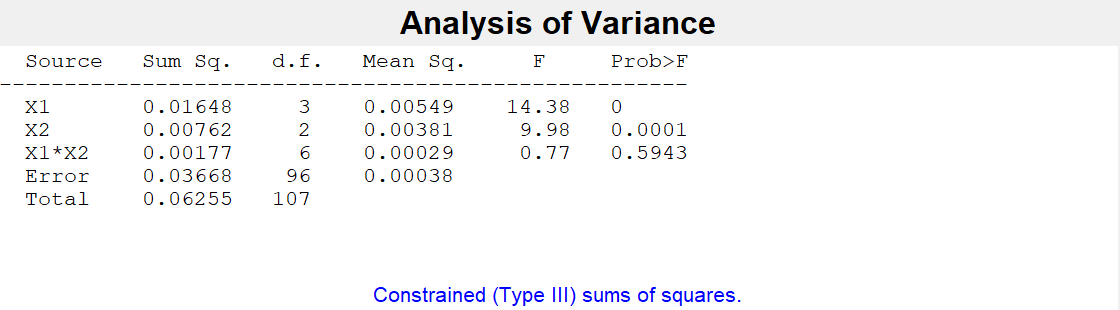

 
 s = septimeH_mat(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### B.3 Temporal interactions in SHK/CTL/RW

% A.Cumulative activity over time

 cumsum_f_a_d1 = nan(length(u_paircodes), 601, length(condvec));
h_cs_f_a = nan(length(u_paircodes), length(condvec));
 
 for k = 1:length(condvec)
    for i = 1:length(u_paircodes)
        
        curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
  
        cumsum_f_a_d1(i,:,k) = cumsumbehav(curind,:);
        h_cs_f_a(i,k) = cumsumbehav_ht(curind);
         
    end
 end
 

Display cumsums

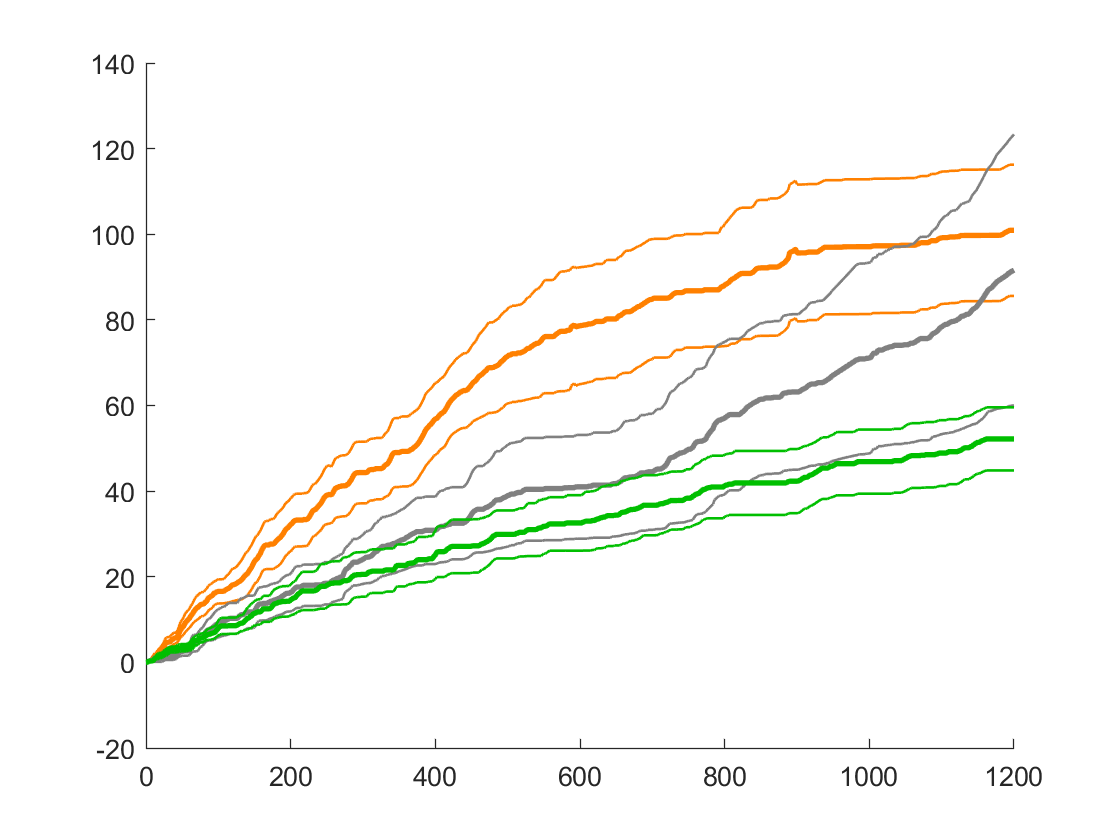

% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
% hold on
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
% 


figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'Color', [1 .5 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'Color', [.5 .5 .5]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'Color', [0 .75 0]);

box off


 for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,2));
 end
 [min_SHK_CTL locmin_1_45] = min(b)

min_SHK_CTL = 7.2550e-04

locmin_1_45 = 353

  for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,3));
  end
  [min_SHK_RWD locmin_1_24] = min(b)

min_SHK_RWD = 0.0013

locmin_1_24 = 255

    for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,2)-cumsum_f_a_d1(:,i,3));
    end
    [min_CTL_RWD locmin_45_24] = min(b)

min_CTL_RWD = 0.0322

locmin_45_24 = 12

Compare latency to half-amplitude

[a b] = ttest(h_cs_f_a(:,1)-h_cs_f_a(:,2))

a = 0

b = 0.0635

Latency data: Compute the matrix for this experiment

% latmat_f = nan(length(u_paircodes), length(phystypes), length(condvec));
% latmat5_f = nan(length(u_paircodes), length(phystypes), length(condvec));
%  for i = 1:length(u_paircodes)
%      for k = 1:length(condvec)
%          curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
%          latmat_f(i,:, k) = be_lat(curind,:);    
%          latmat5_f(i,:,k) = be_lat5(curind,:);
%      end
%  end

Display latencies, collective

%  f = figure
% lm = min(latmat_f, [], 2);
% bar(nanmean(squeeze(lm)), 'k')
% hold on
% errorbar(1:3, nanmean(squeeze(lm)), nanstd(squeeze(lm))/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
% box off
% set(get(f, 'Children'), 'XTick', [1:3])
% set(get(f, 'Children'), 'XTickLabel', xticklabels);

% slm = squeeze(lm);
% p = anova_rm(squeeze(slm));

Display the latencies across types

% titlecell = {'agonistic', 'body sniffing', 'rear sniffing', 'face-to-face'};
% 
%  figure
%  
%  for i = 1:length(betypes)
%     d = subplot(length(betypes),1,i);
%     
%     errorbar(1:length(condvec), nanmean(squeeze(latmat5_f(:, i,:))), nanstd(squeeze(latmat5_f(:,i,:)))/sqrt(8), 'k');
% %    hold  on
%    set(d, 'XLim', [.75 3.25]);
%    set(d, 'XTick', [1:3])
%    if i < 4
%        set(d, 'XTickLabel', {'' '' '' });
%    else
%        set(d, 'XTickLabel', xticklabels);
%    end
%    title(titlecell{i});
%     box off
%  end

Stats on latencies

% for i = 1:4
%     [a(i) b(i)] = ttest(squeeze(latmat5_f(:,i,1)- latmat5_f(:,i,2)));
%   %   [psub(i,:) j] = anova_rm(squeeze(latmat5_f(:,i,1:2)));
% %     sheetnum = ['Sheet' num2str(i)];
% %     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
% end
% b

### B.4 Temporal relationship between physical interactions

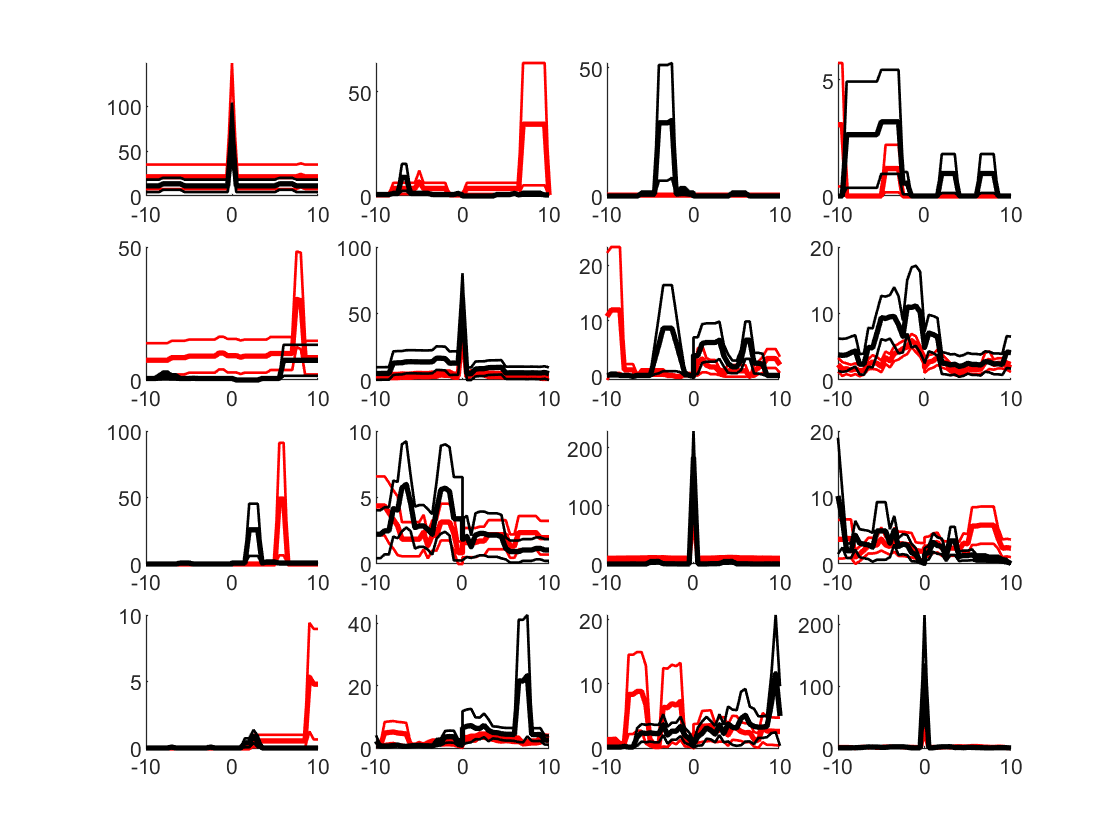


%  exp_ind = find(strcmp(rdb.experiment, 'cof'));
%  
%  cof_iso_ind = intersect(exp_ind, find(rdb.condition(:,4) == 0));
%  cof_sep_ind = intersect(exp_ind, find(rdb.condition(:,4) == 1));
%  cof_min_ind = intersect(exp_ind, find(rdb.condition(:,2) == 1/60));
%  
  cofind = cell(3,1);
  for i = 1:3
      cofind{i} = intersect(find(rdb.condition(:,1) == condvec(i)), exp_ind);
  end

colorcodes = [1 0 0; 0 0 0; 0 0 1];

figure
%i = 1;
for i = [1 2]
    for j = 1:16
        subplot(4,4,j);
        hold on
        curind = cofind{i};

        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(i,:))  ;  
%        hold on
%        errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,curind))'), nanstd(squeeze(SH_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(2,:))  ; 
        box off
    end    
    
end

% stats 

n1 = 2;
n2 = 3;

mxc = nan(size(be_xcorr,1), 2, size(be_xcorr,3));

mxc(:,1,:) = nanmean(be_xcorr(:,1:19,:),2);
mxc(:,2,:) = nanmean(be_xcorr(:,23:42,:),2);

sxc(:,1,:) = nanmean(SH_xcorr(:,1:19,:),2);
sxc(:,2,:) = nanmean(SH_xcorr(:,23:42,:),2);

cofind;

for i = 1:16
    [asi1(i), bsi1(i)] = ttest2(mxc(i,1,cofind{n1}), mxc(i,1,cofind{n2}));
end

for i = 1:16
    [asi2(i), bsi2(i)] = ttest2(mxc(i,2,cofind{n1}), mxc(i,2,cofind{n2}));
end

[codes(:,1:2,1) bsi1' bsi2']

ans =     1.0000    1.0000    0.5649    0.5603
    1.0000    2.0000    0.3310    0.4566
    1.0000    3.0000    0.5386    0.5761
    1.0000    4.0000    0.6308    0.0061
    2.0000    1.0000    0.6014    0.5523
    2.0000    2.0000    0.1528    0.3942
    2.0000    3.0000    0.5192    0.4665
    2.0000    4.0000    0.3330    0.3773
    3.0000    1.0000    0.5761    0.4858
    3.0000    2.0000    0.4562    0.5602


2-way repeated measures ANOVA in R

% for i = 1:size(latmat_f)
%     nlatmat_f(i,:,:) = squeeze(latmat5_f(i,:,:))';    
% end
%Create_2way_R_table(nlatmat_f(:,1:2,:));
 
 % Have to use R script for stats (e.g., repeatedmeasures_NIscript.R)
 
 

## C: Vocalizations

### C.1 Summed vocalizations

sumvoc -- all syllables

nsumvoc -- all syllables, exclusing nans

csumvoc -- syllables combined into "calls"

rsumvoc -- the rate of syllables, rather than the proportion of time (number instead of time) 

%

%A lot of this code comes directly from reunionOTRA2.mlx

sv = rsumvoc; %plug in another option, depending on interest

 sepvoctime_mat = nan(length(u_paircodes),length(cofind));
 vocnum_mat = sepvoctime_mat;
% svt_4 = nan(length(u_paircodes),3,2);
% side_svt = svt_4;

 for i = 1:length(u_paircodes)
     for k = 1:length(cofind)
         curind = intersect(find(rdb.paircode' == u_paircodes(i)), cofind{k});
         sepvoctime_mat(i, k) = sv(curind,:);    
         vocnum_mat(i, k) = nsumvoc(curind,:); %this is a weird way to jump back to the voc nums, but moving on 
     end
 end
 


### C.2 By type

 f = figure

f =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 126
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


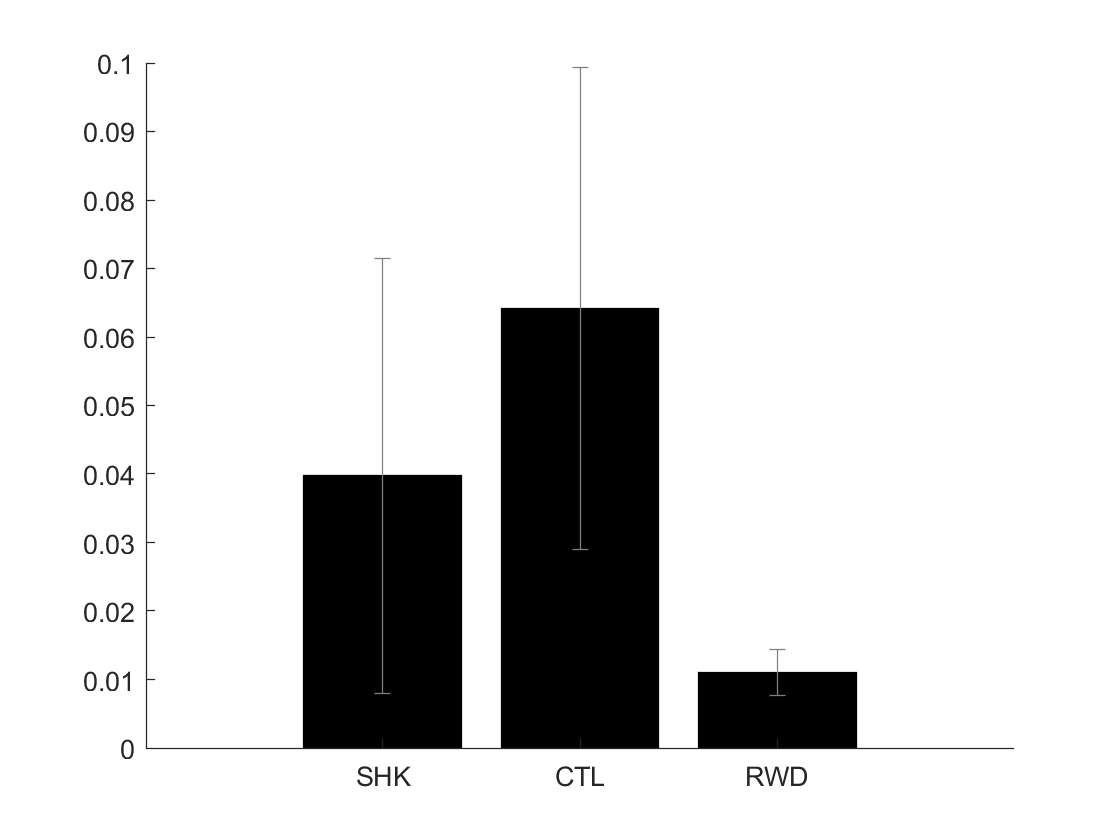

 curmat = sepvoctime_mat;
%curmat = vocnum_mat;

 bar(nanmean(curmat), 'k')
hold on
errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', xticklabels);

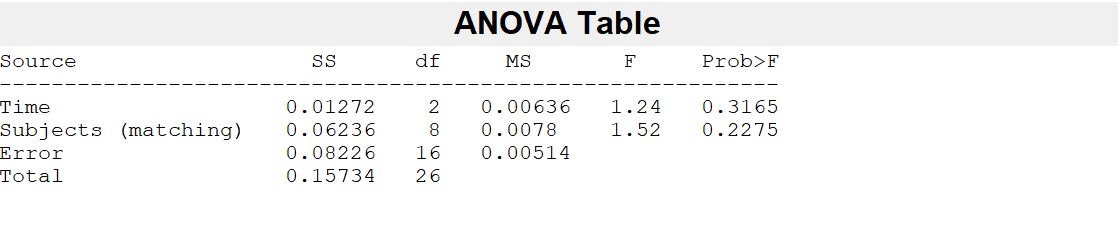

p = anova_rm(sepvoctime_mat);

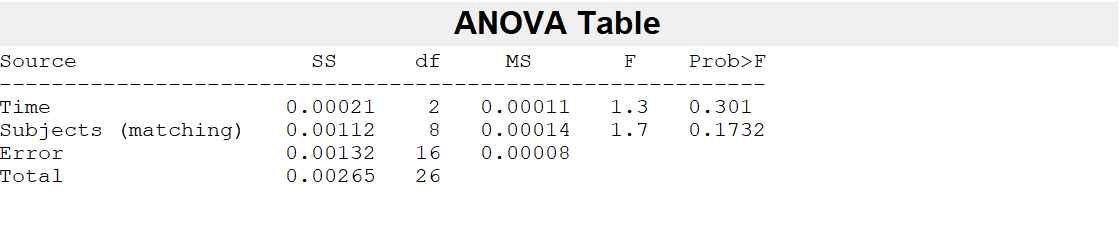



p = anova_rm(vocnum_mat);

 cumsum_f_a_d1 = nan(length(u_paircodes), 601, length(condvec));
h_cs_f_a = nan(length(u_paircodes), length(condvec));
 
 for k = 1:size(sepvoctime_mat,2)
    for i = 1:size(sepvoctime_mat,1)
     
            curind = cofind{k}(i);  
            cumsum_f_a_d1(i,:,k) = cumsumvoc(curind,:);
            h_cs_f_a(i,k) = cumsumvoc_ht(curind);
        
    end
 end
 

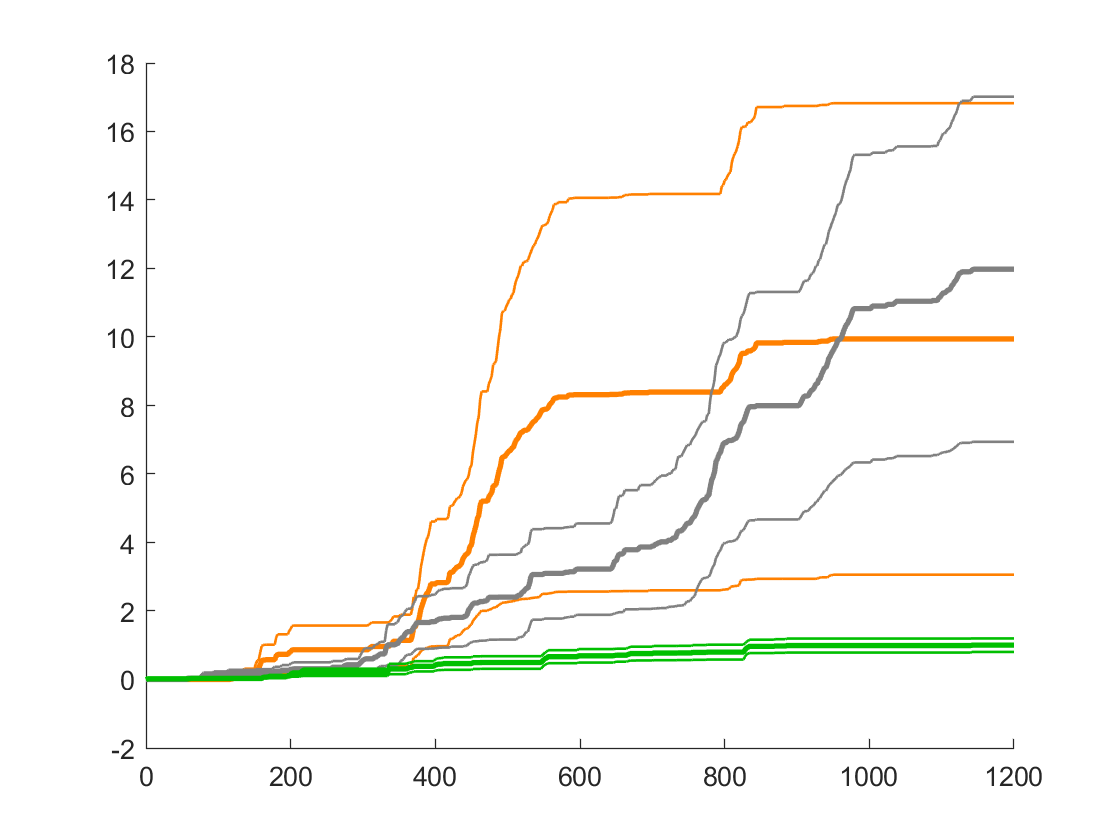

figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'Color', [1 .5 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'Color', [.5 .5 .5]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'Color', [0 .75 0]);

box off


sv = rvoc;

sepvoctime_mat_full = nan(length(u_paircodes), length(cofind), length(indvocsgood));

 for i = 1:length(u_paircodes)
     for k = 1:length(cofind)
        curind = intersect(find(rdb.paircode == u_paircodes(i)), cofind{k});

         sepvoctime_mat_full(i, k, :) = sv(curind,:);    
     end
 end

Figures

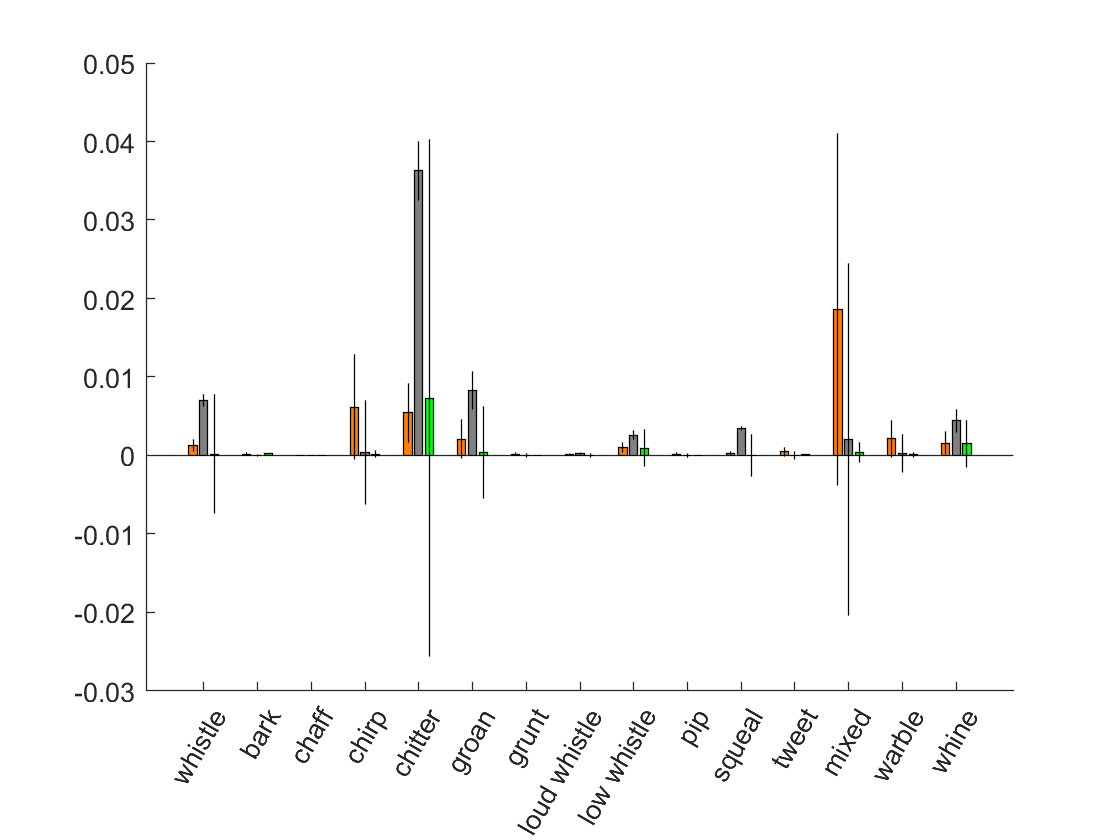

 f4 = figure;


 hold on
b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [1 .5 0]);
b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [.5 .5 .5]);
b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [0 1 0]);
e1 = errorbar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e2 = errorbar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e3 = errorbar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:) )), squeeze(nanstd(sepvoctime_mat_full(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
%bar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), 'BarWidth', .35);
%errorbar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), squeeze(nanstd(voctime_mat(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none');
set(get(f4, 'Children'), 'XTickMode', 'manual')
set(get(f4, 'Children'), 'XTick', 1:15)
ivg = indvocsgood; %([1:6 8:end]);
set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
set(get(f4, 'Children'), 'XTickLabelRotation', 60)

curmat = sepvoctime_mat_full;

s = size(curmat);

toprowDM = cell(1,s(2)*s(3));
idatamat = cell(s(2)*s(3),2);
for i = 1:s(2)
    for j = 1:s(3)
        toprowDM{i+(j-1)*s(2)} = ['B' num2str(i) 'C' num2str(j)]; 
        idatamat{i+(j-1)*s(2),1} = ['B' num2str(i)];
        idatamat{i+(j-1)*s(2),2} = ['C' num2str(j)];
    end
end

datamat = num2cell(reshape(curmat, s(1), s(2)*s(3),1));
full_dm = [[{'subject'} toprowDM] ; [num2cell([1:size(datamat,1)]') datamat]];
T = cell2table(full_dm(2:end,:), 'VariableNames', full_dm(1,:));
writetable(T,'datamat.csv');

To do the stats, need to be running R

%!C:\Program Files\R\R-3.6.1\bin\x64\Rscript

full_idm = [{'B' 'C'} ; idatamat];
iT = cell2table(full_idm(2:end,:), 'VariableNames', full_idm(1,:));
writetable(iT,'idatamat.csv');

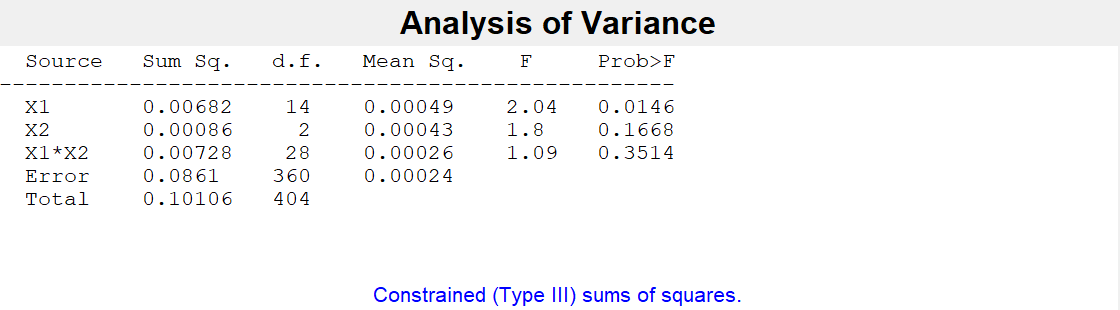

 s = sepvoctime_mat_full(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

for i = 1:15
    [a(i) b(i)] = ttest(sepvoctime_mat_full(:,1,i)-sepvoctime_mat_full(:,2,i));
end
a

a =      0     0   NaN     0     0     0     0     0     0     0     0     0     0     0     0


b

b =     0.4028    0.3466       NaN    0.2868    0.2405    0.2133    0.3466    0.6456    0.4636    0.3466    0.1820    0.3466    0.3880    0.3844    0.1094


### C.3 Clustering

 condvec = [5 2 4]; % 1 min 45 min 1 day 

for i = 1:length(u_paircodes)
    for j = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(j)), exp_ind);
        indmat(i,j) = curind;
            f_inds= find(indfeat_nn(:,1) == curind); 
            inds{i,j} = f_inds;
            if isempty(f_inds)
                dbs = 1;
            end
%        vip_inds{i,j} = intersect(inds{i,j}, vocind_best);
        end
 end


Assess significance of the clusters

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 2]), 0, [], 9);
%save shkntr_sigclusts pvals_c ef_c val_c
load shkntr_sigclusts

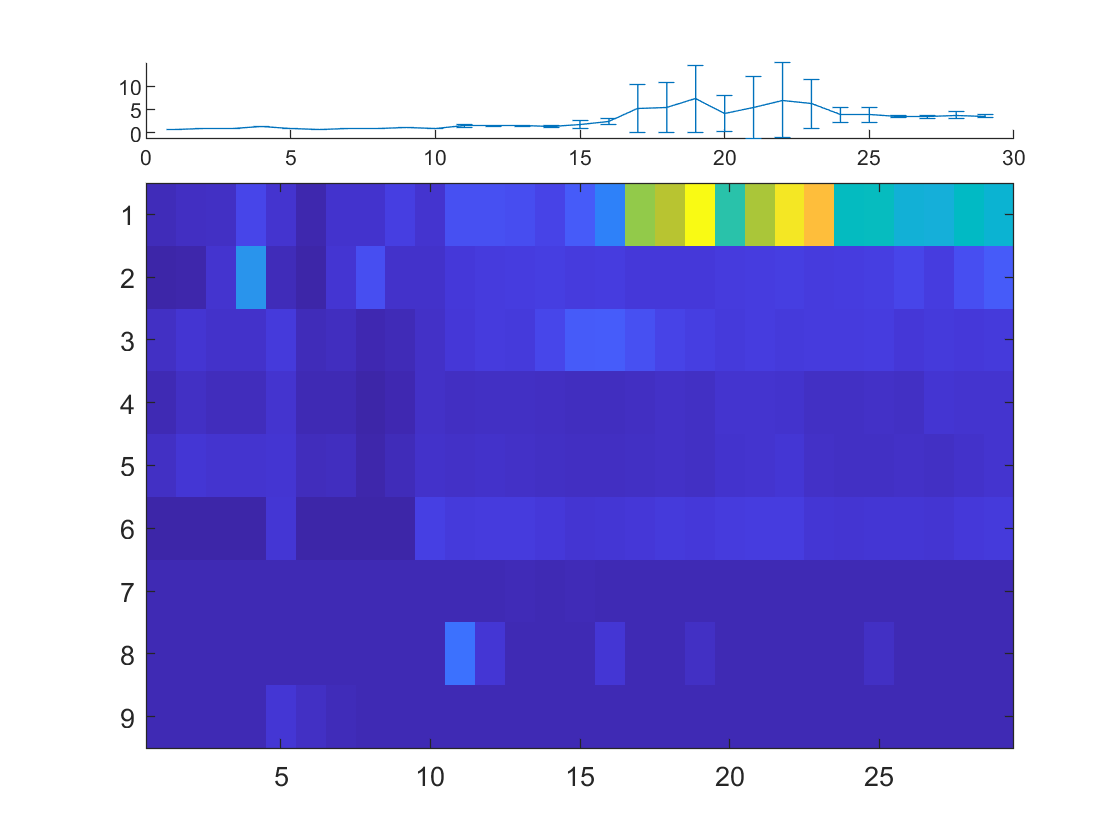

if length(find(~isnan(pvals_c{end}))) == 0
    pvals_c = pvals_c(1:end-1);
    ef_c = ef_c(1:end-1);
    val_c = val_c(1:end-1);
end

[shkntr_prevocbest, shkntr_vocindbest, shkntr_ircm, shkntr_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);

shkntr_nm

shkntr_nm =     0.0153    0.0412    0.0904    0.2390    0.2198    0.1738    0.5000    0.5000    0.3888


Manually set the number of iterations with quality clusters (typically based on nm < 0.05)

goodc = 1;

What are the features and manual classifications associated with the most differentially expressed vocalization?

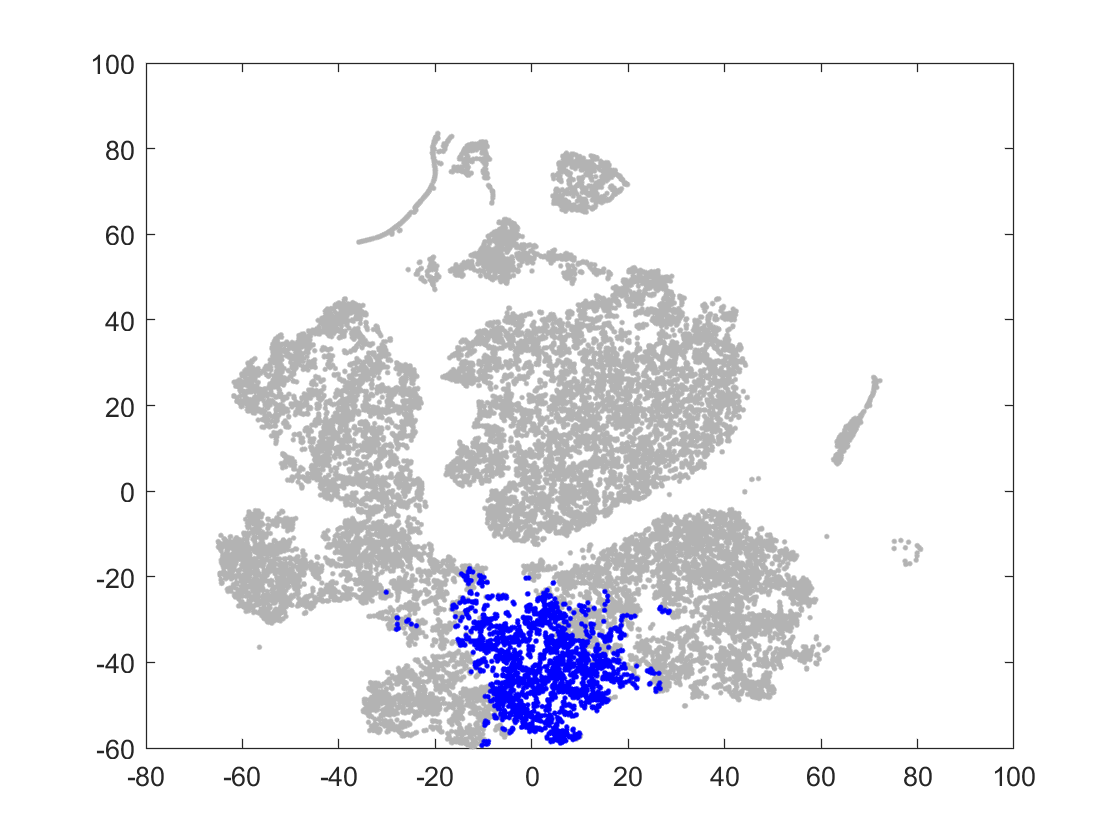

Current plot held


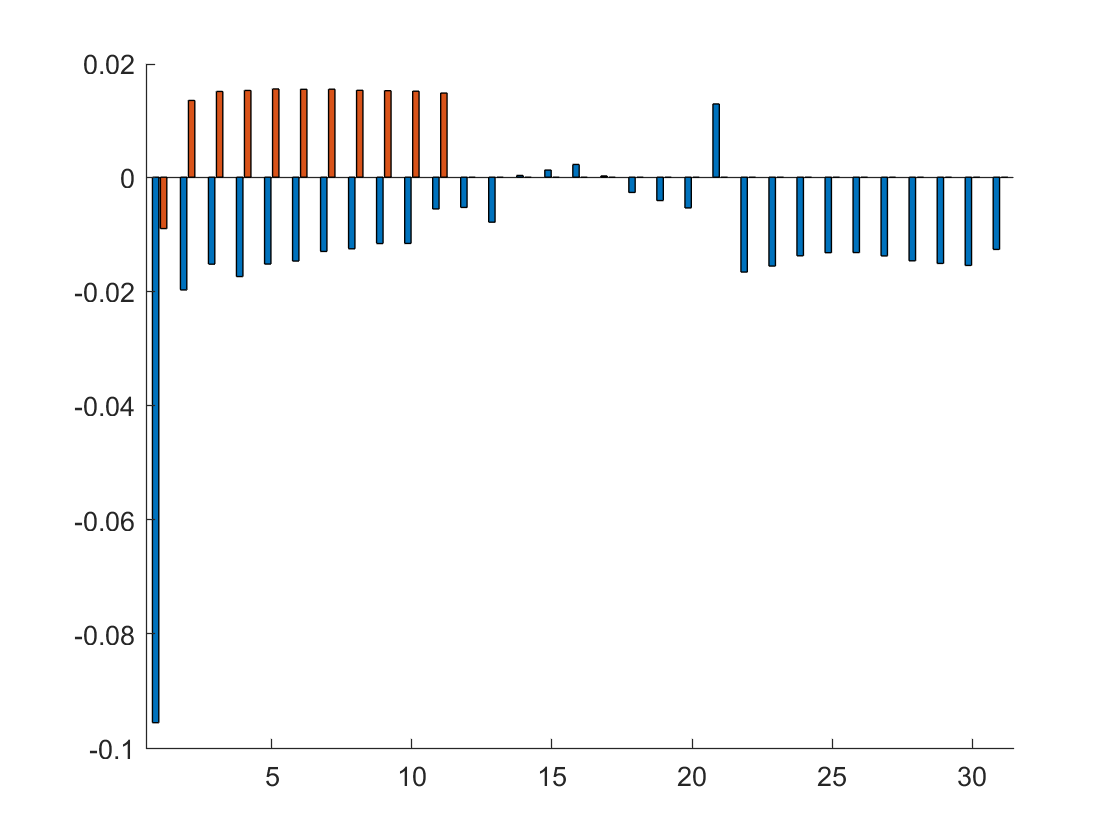

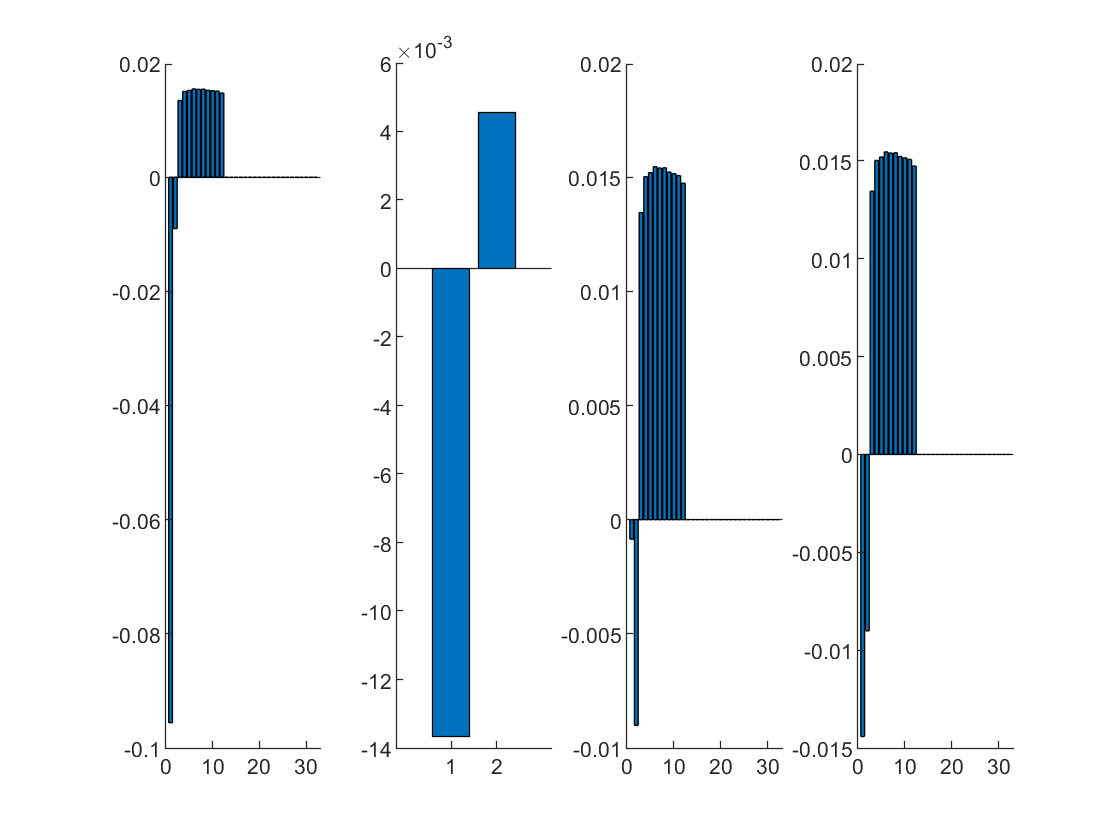

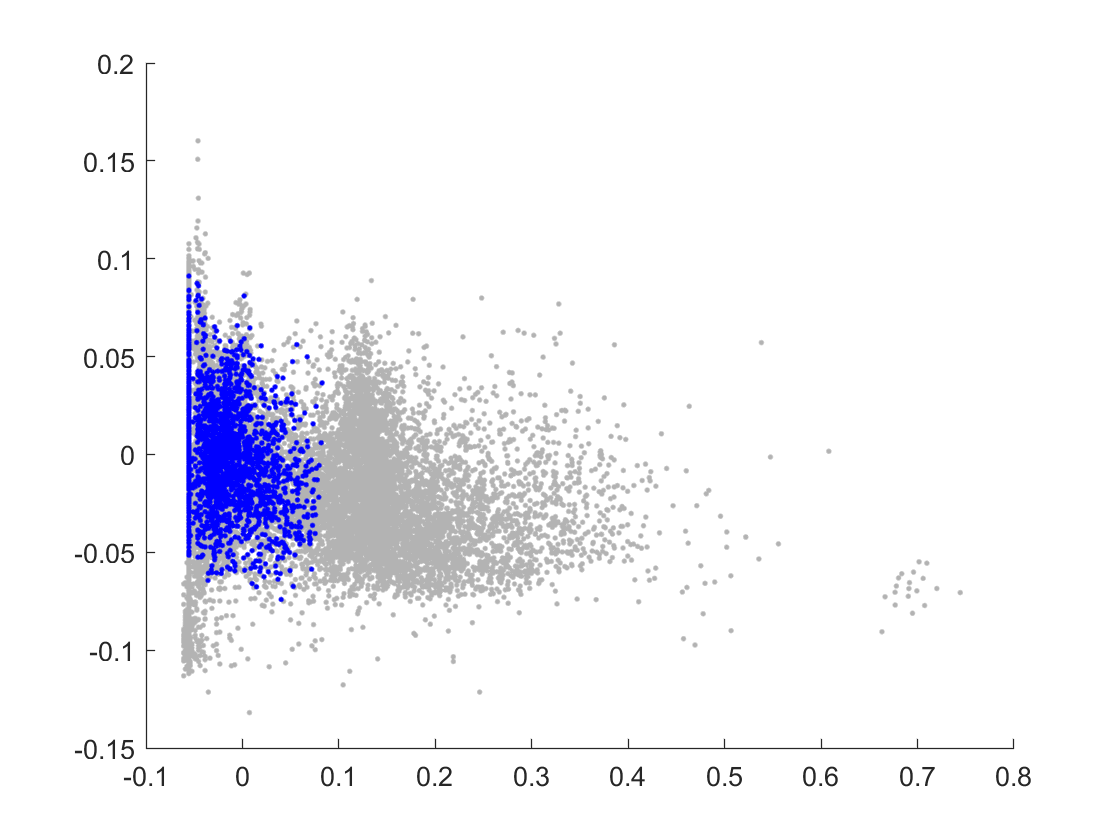

Current plot held


h5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 137
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


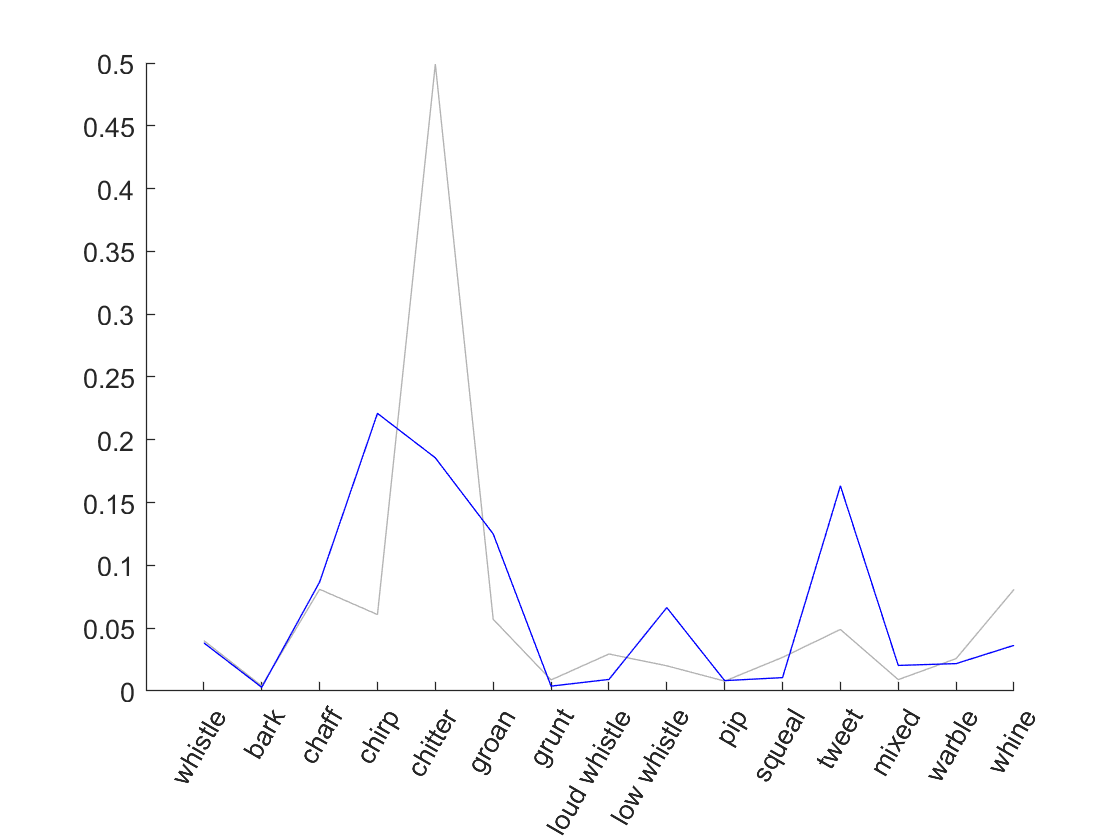

Current plot held


[h1, h2, h3, h4] = sigclust_Figures(shkntr_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

Repeat for shk vs. rwd

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 3]), 0, [], 9);
%save shkrwd_sigclusts pvals_c ef_c val_c
load shkrwd_sigclusts

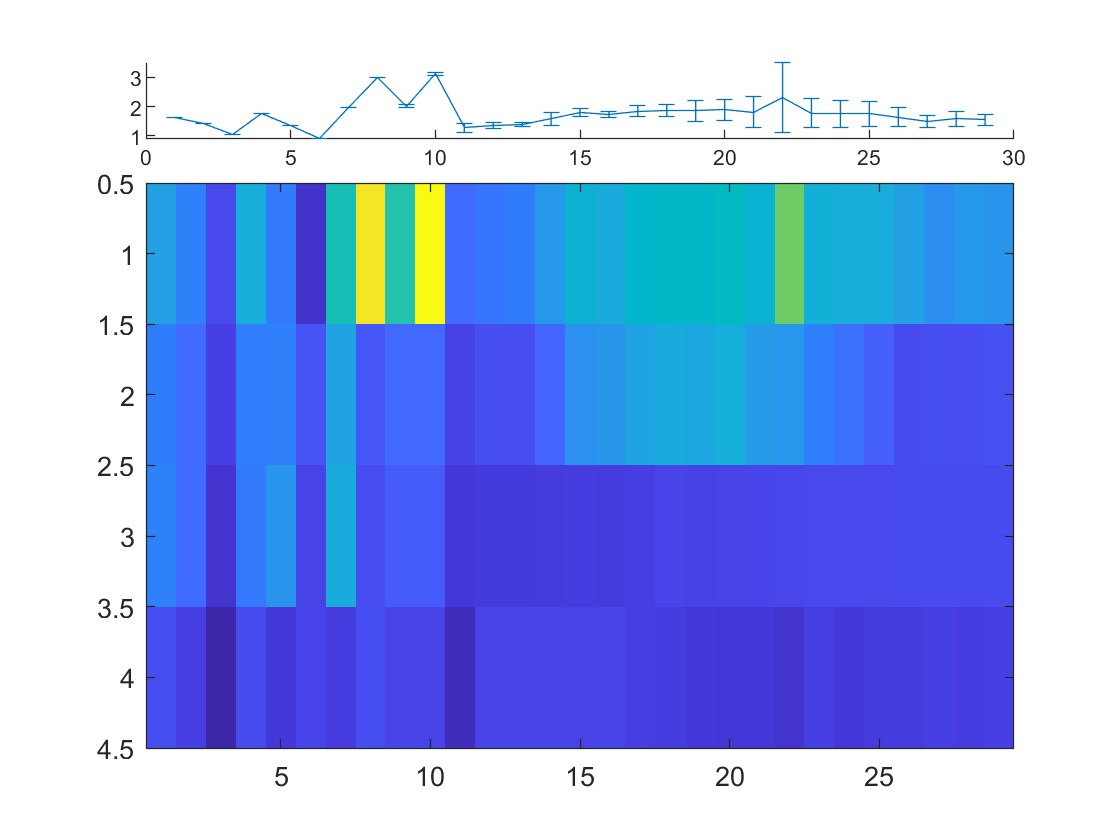

if length(find(~isnan(pvals_c{end}))) == 0
    pvals_c = pvals_c(1:end-1);
    ef_c = ef_c(1:end-1);
    val_c = val_c(1:end-1);
end

[shkrwd_prevocbest, shkrwd_vocindbest, shkrwd_ircm, shkrwd_nm] = process_sigclusts(pvals_c, ef_c, val_c, idx, indfeat_nn);

shkrwd_nm

shkrwd_nm =     0.0329    0.0878    0.0965    0.2004


Manually set the number of iterations with quality clusters (typically based on nm < 0.05)

goodc = 1;

What are the features and manual classifications associated with the most differentially expressed vocalization?

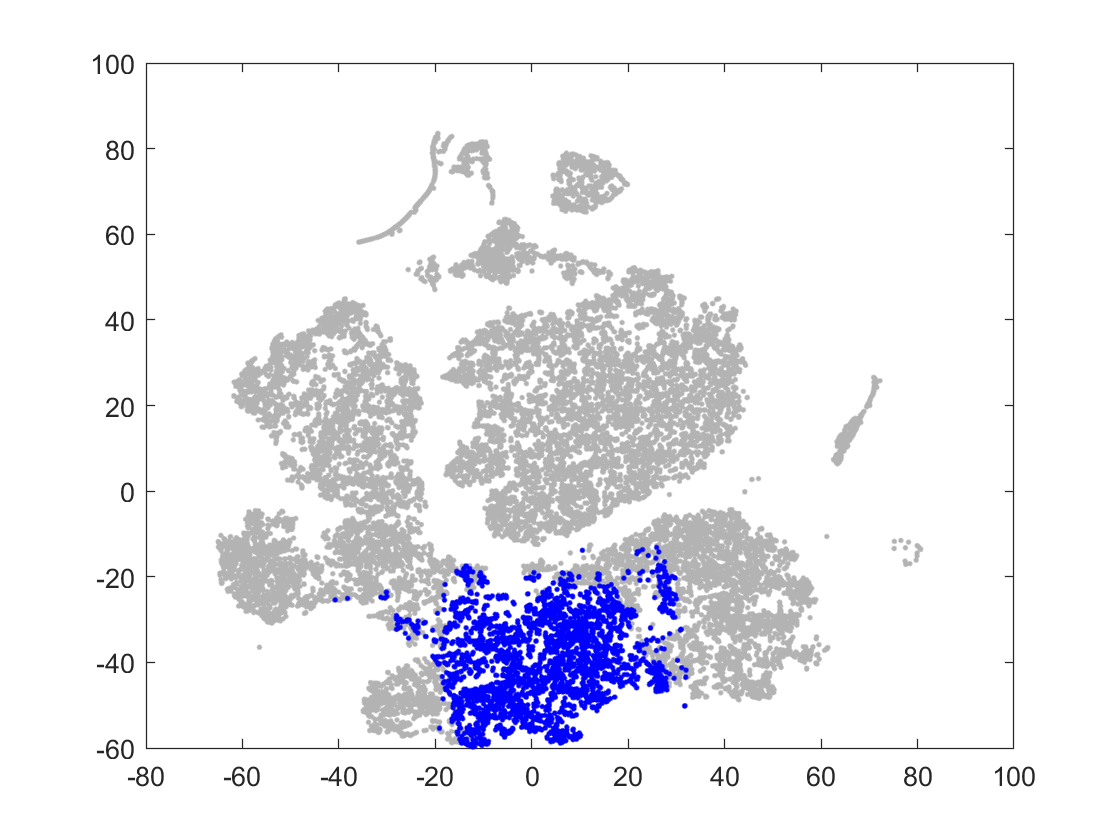

Current plot held


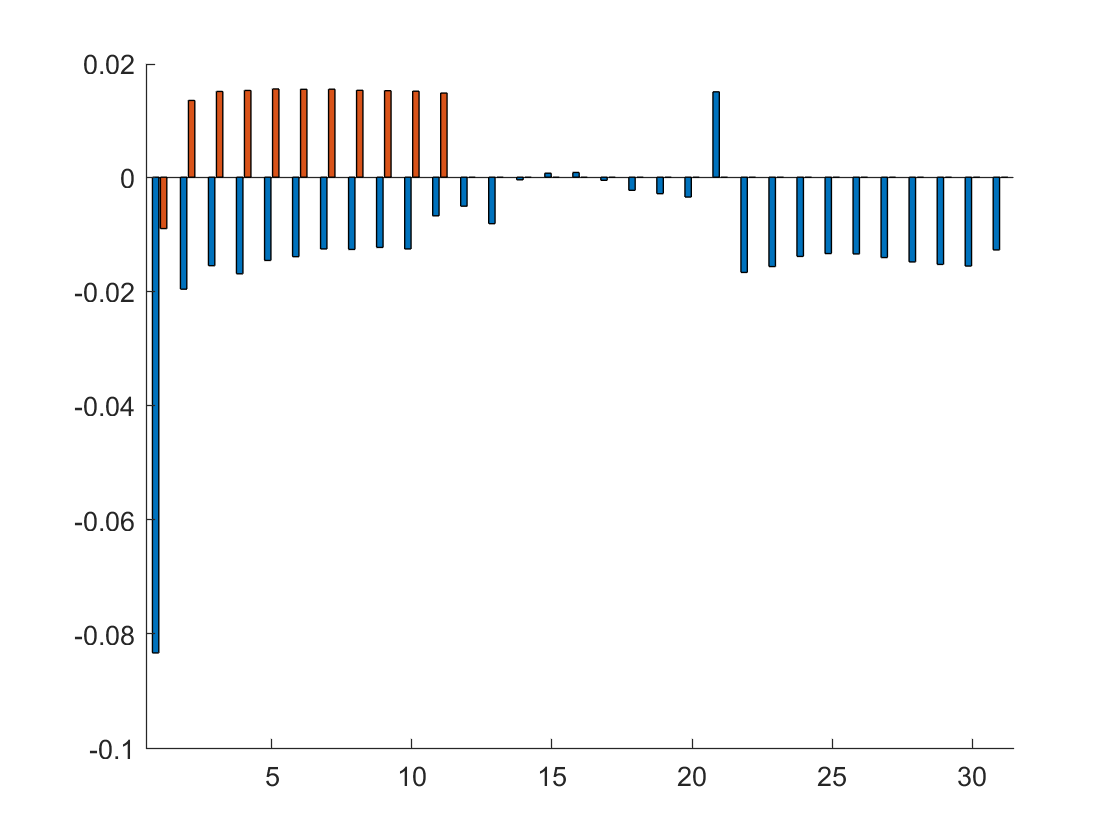

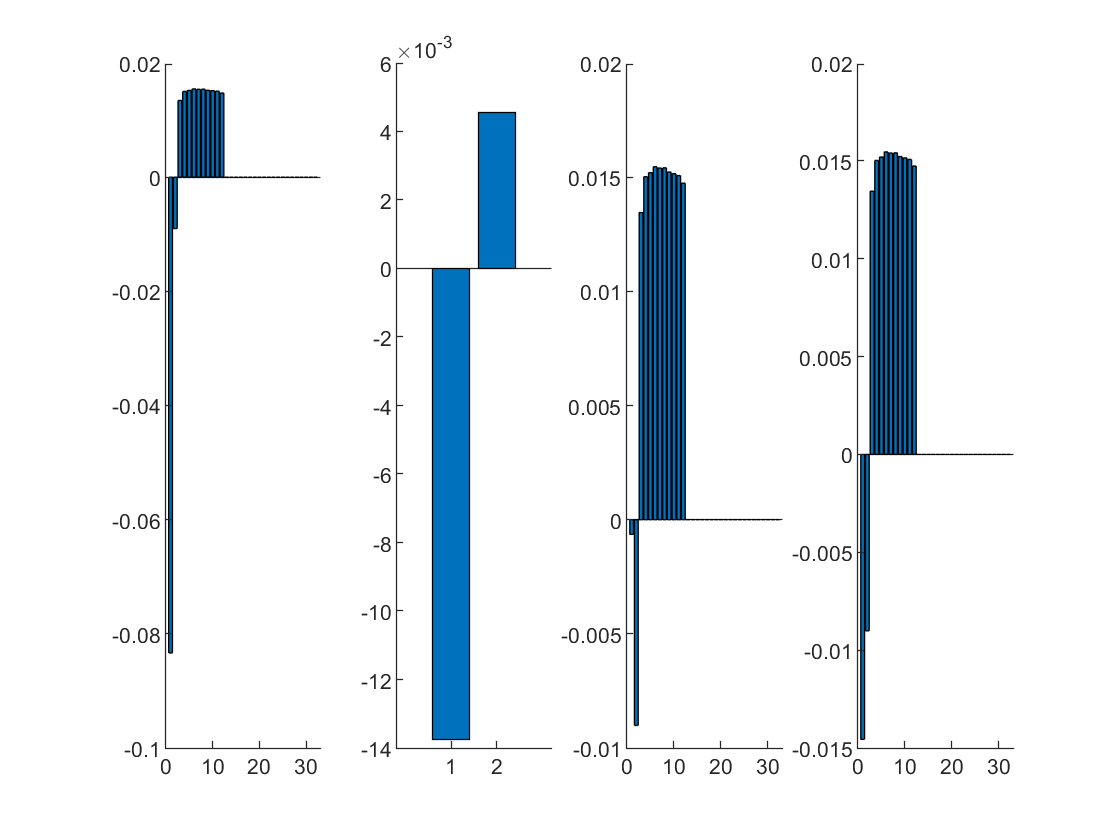

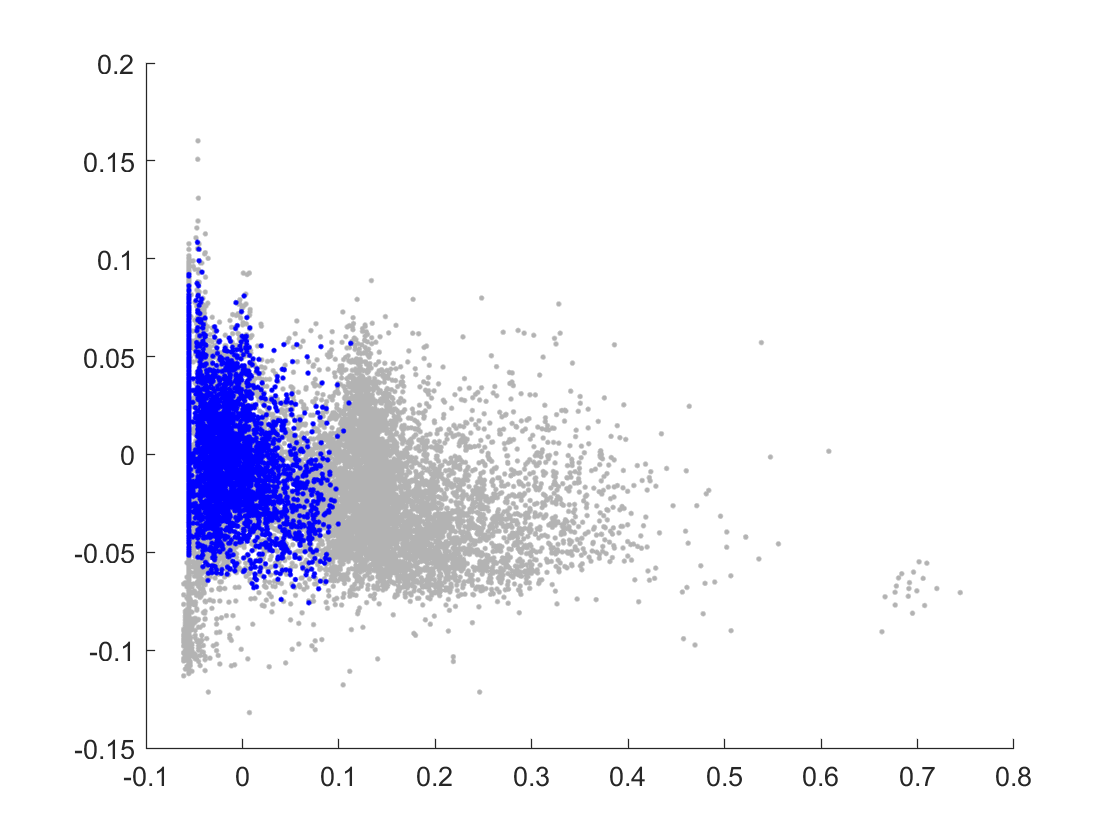

Current plot held


h5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 143
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


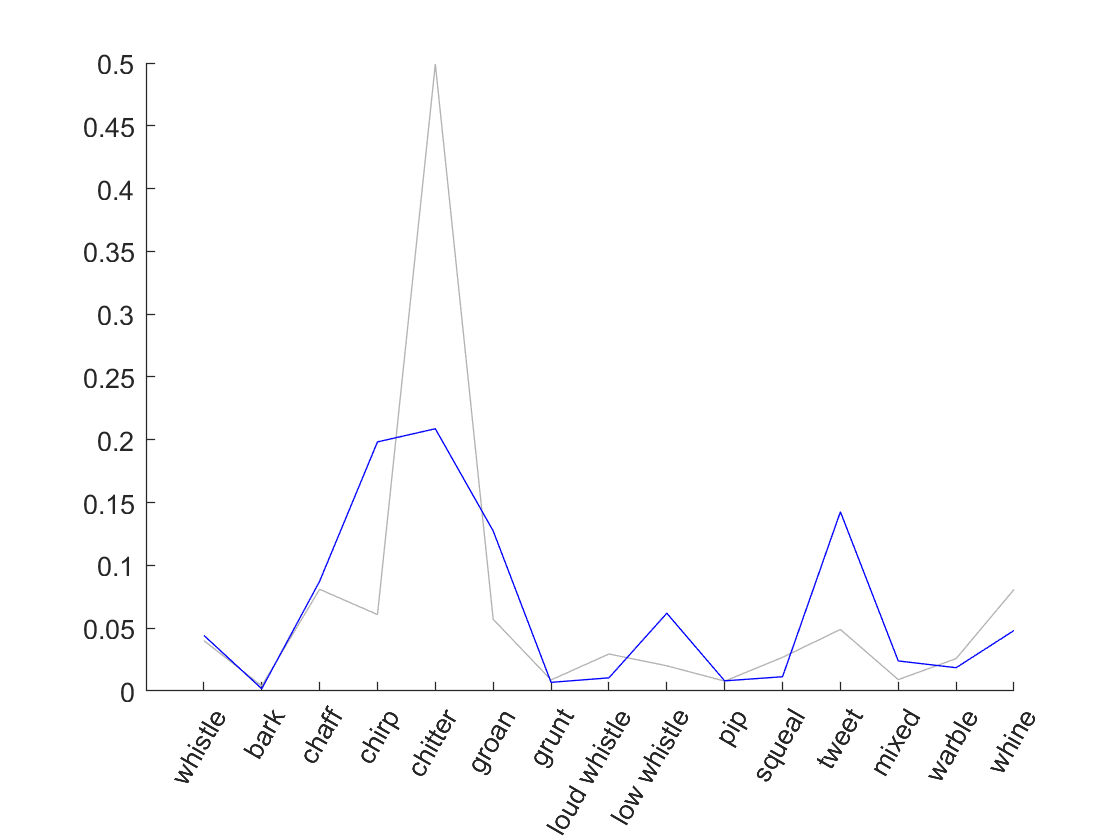

Current plot held


[h1, h2, h3, h4] = sigclust_Figures(shkrwd_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

One more: ntr vs. rwd

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[2 3]), 0, [], 1);

1

%save ntrrwd_sigclusts pvals_c ef_c val_c
load ntrrwd_sigclusts

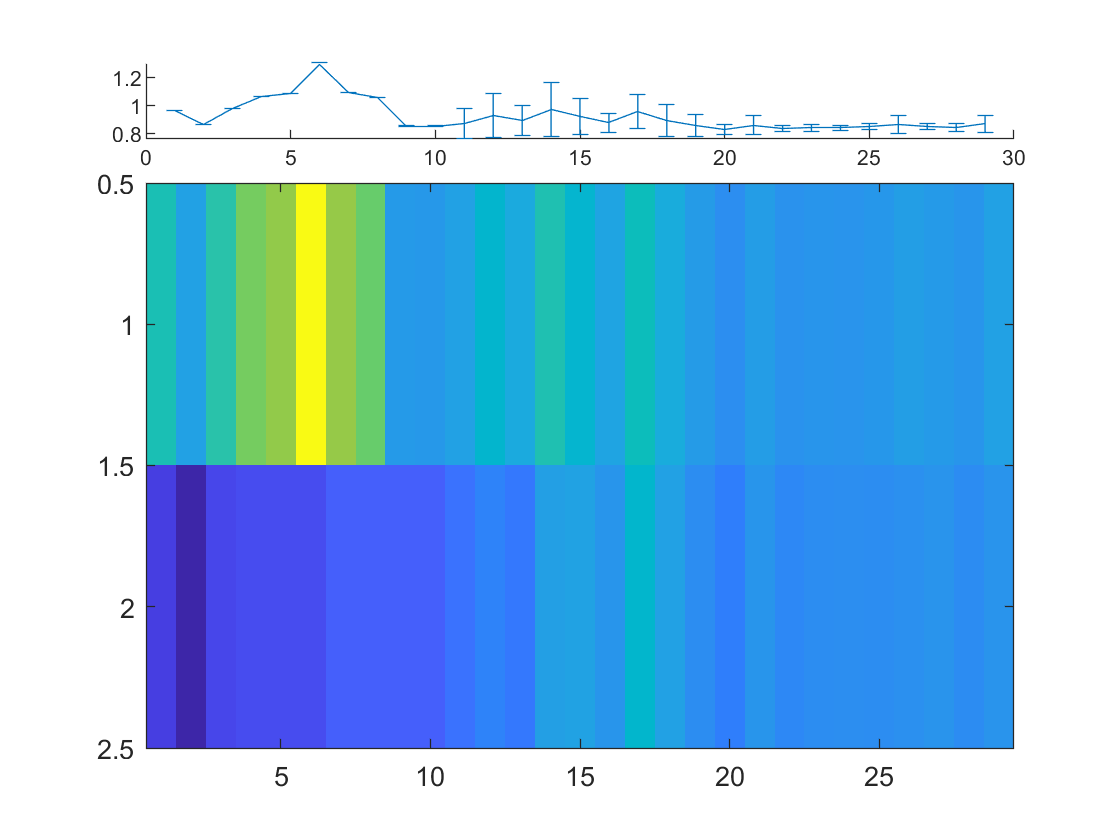

[ntrrwd_prevocbest, ntrrwd_vocindbest, ntrrwd_ircm, ntrrwd_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);

ntrrwd_nm

ntrrwd_nm =     0.0798    0.1421


Manually set the number of iterations with quality clusters (typically based on nm < 0.05)

goodc = 1;

What are the features and manual classifications associated with the most differentially expressed vocalization?

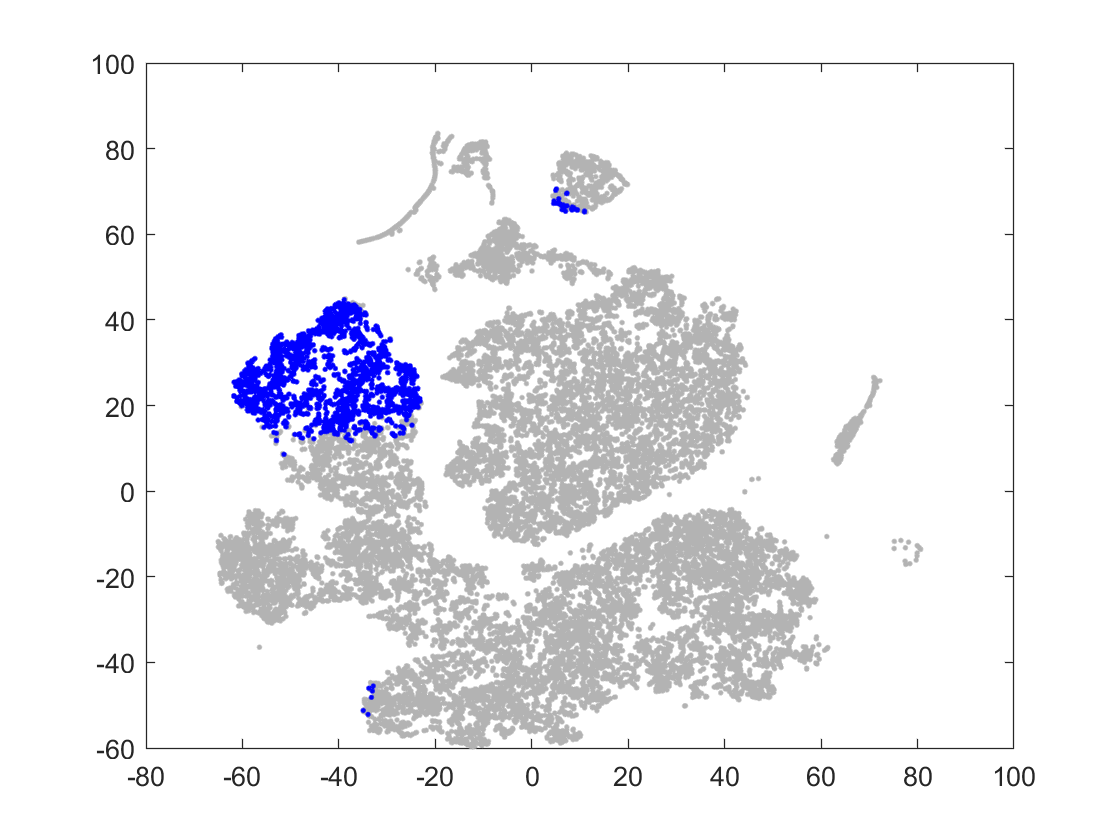

Current plot held


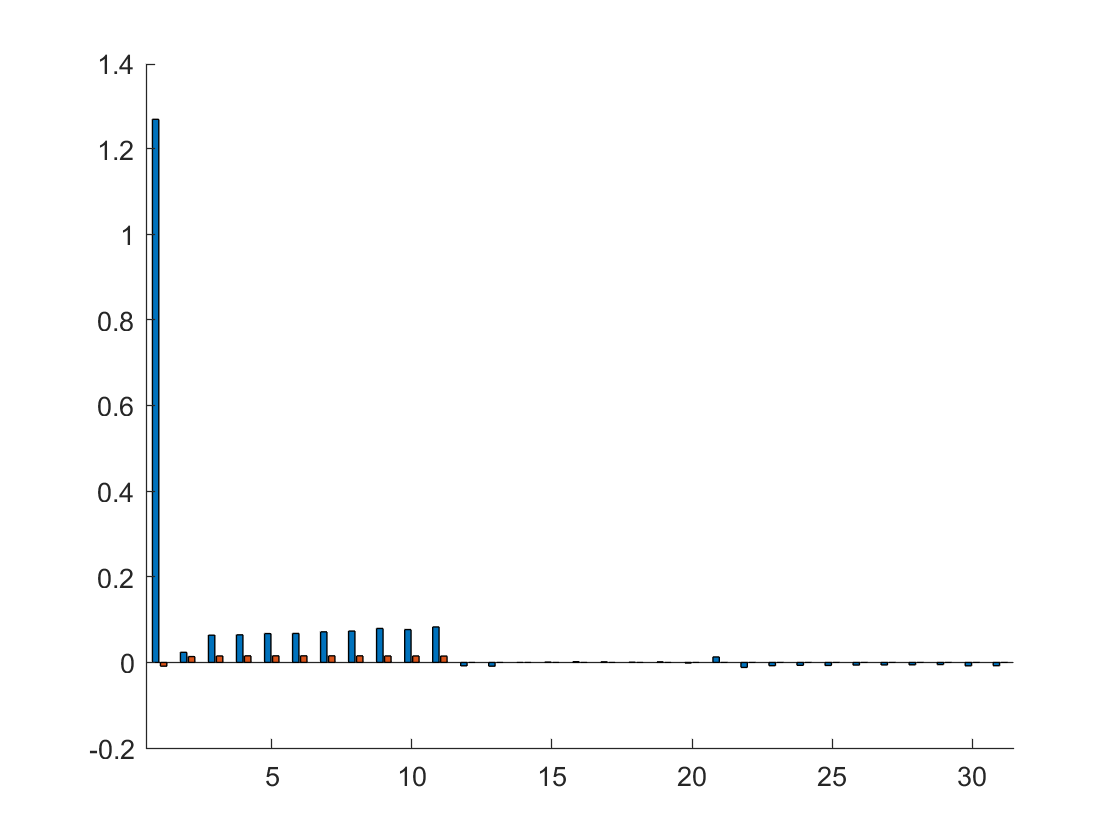

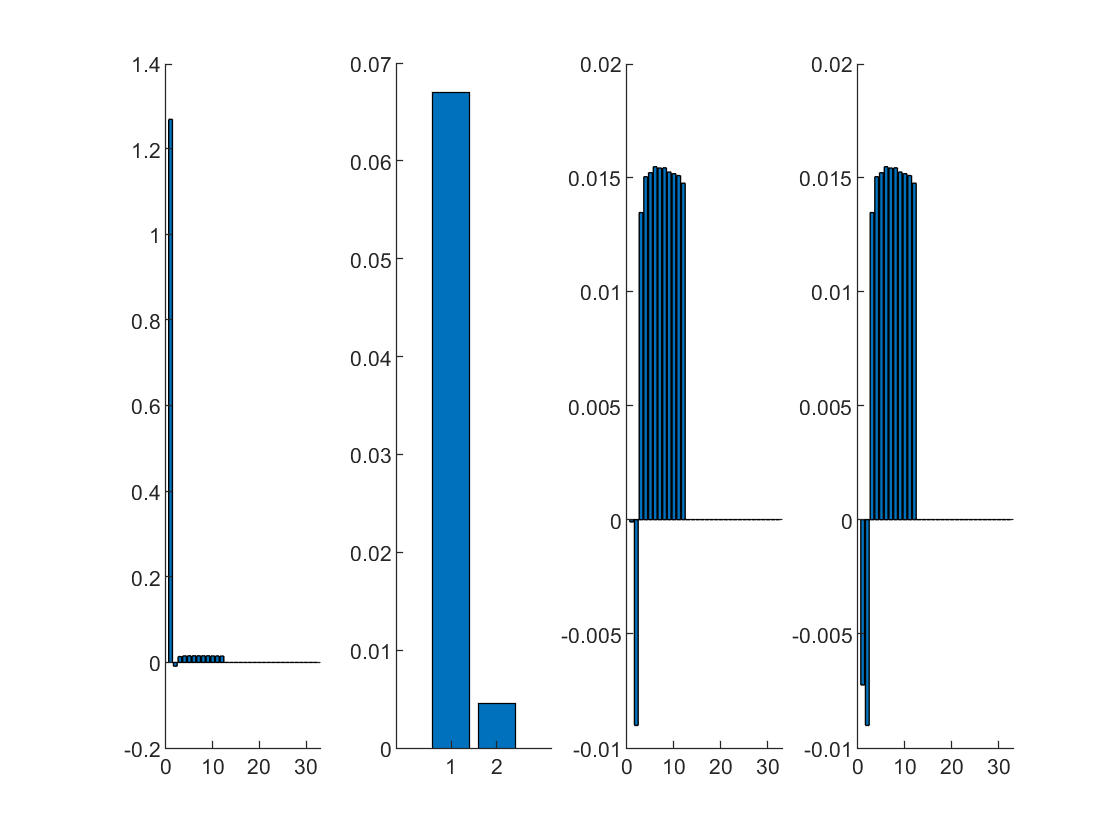

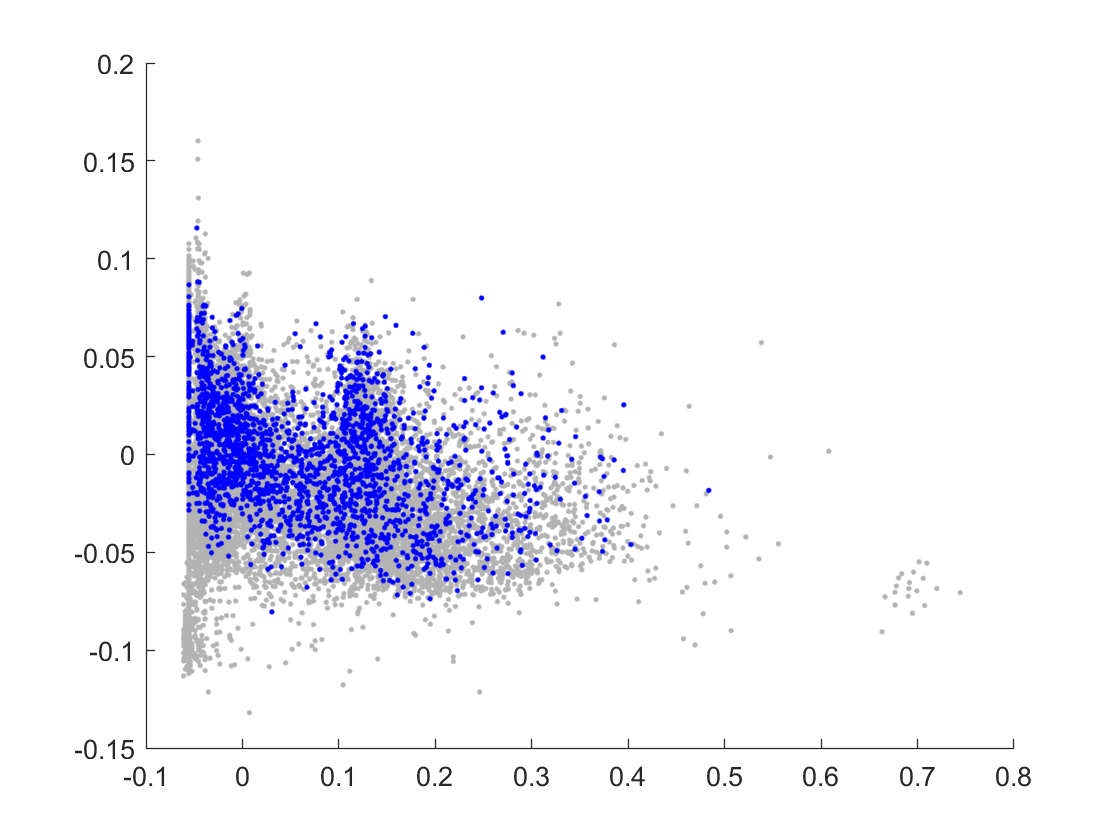

Current plot held


h5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 162
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


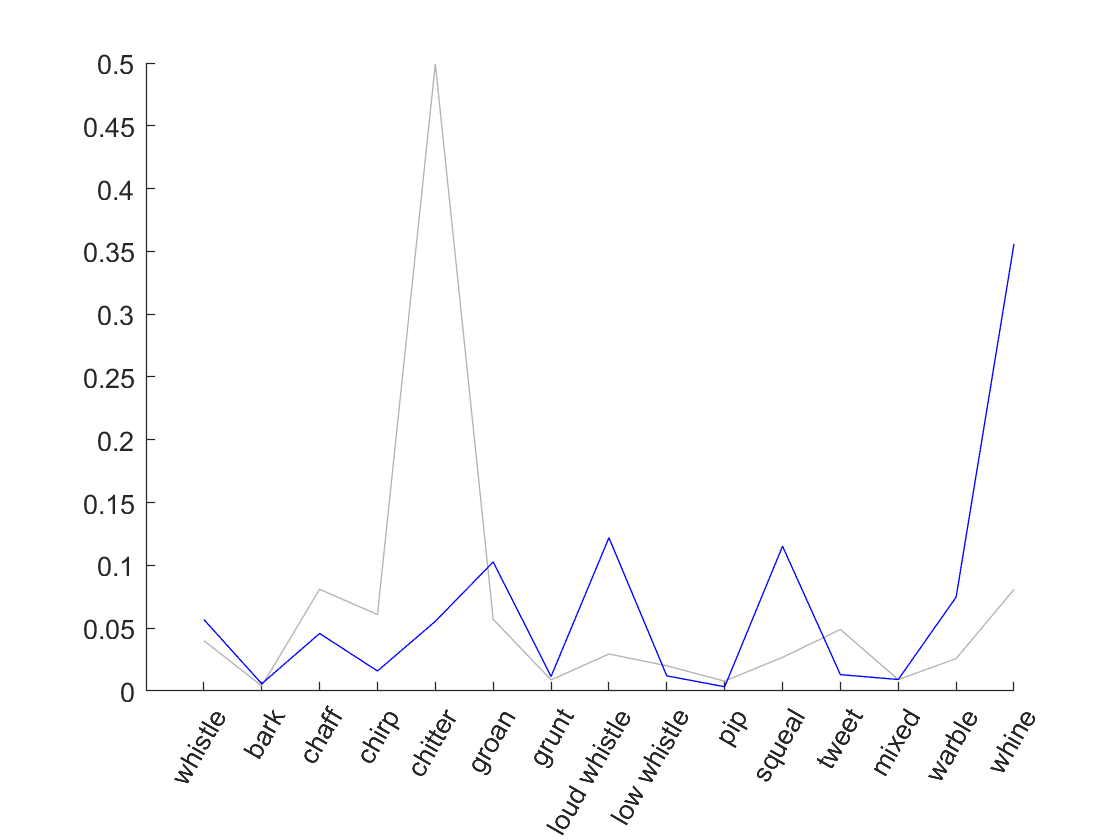

Current plot held


[h1, h2, h3, h4] = sigclust_Figures(ntrrwd_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

load shkntr_sigclusts
shkntr_pvals = pvals_c;
shkntr_ef = ef_c;
shkntr_vals = val_c;

load shkrwd_sigclusts
shkrwd_pvals = pvals_c;
shkrwd_ef = ef_c;
shkrwd_vals = val_c;

load ntrrwd_sigclusts
ntrrwd_pvals = pvals_c;
ntrrwd_ef = ef_c;
ntrrwd_vals = val_c;

% load iso2_sigclusts
% iso2_pvals = pvals_c;
% iso2_ef = ef_c;
% iso2_vals = val_c;


[shkntr_pvals{1}(shkntr_ircm(1,2), shkntr_ircm(1,1), shkntr_ircm(1,3))...
    shkntr_vals{1}(shkntr_ircm(1,2), shkntr_ircm(1,1), shkntr_ircm(1,3))]

ans =     0.0006    0.1944


[ntrrwd_pvals{1}(ntrrwd_ircm(1,2), ntrrwd_ircm(1,1), ntrrwd_ircm(1,3))...
    ntrrwd_vals{1}(ntrrwd_ircm(1,2), ntrrwd_ircm(1,1), ntrrwd_ircm(1,3))]

ans =     0.0798    0.1169



[shkrwd_pvals{1}(shkrwd_ircm(1,2), shkrwd_ircm(1,1), shkrwd_ircm(1,3))...
    shkrwd_vals{1}(shkrwd_ircm(1,2), shkrwd_ircm(1,1), shkrwd_ircm(1,3))]

ans =     0.0303    0.1037
